## **Creating a "clean" signal **

fs = 44100; %this sampling frequency is standard for audio
T = 0.5;
f_sin = 1000;
t_sin = 0:1/fs:T

t_sin =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011



f1 = sin(2*pi*f_sin*t_sin);

## **Uploading a recorded audio**

recorded_signal = audioread("C:\Users\saray\Downloads\aud2.wav");
recorded_signal=recorded_signal(1:length(f1));

## **Plotting continous signals**

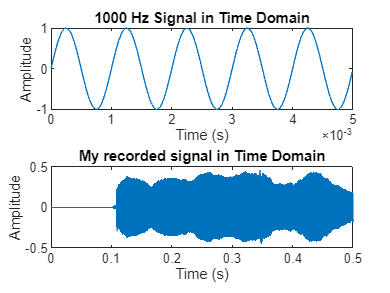

zoom = 0:1/fs:0.005; %I zoomed it to see clearly the signal
figure;
subplot(2,1,1);
plot(zoom, f1(1:length(zoom)));
title('1000 Hz Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t_sin, recorded_signal(1:length(t_sin)));
title('My recorded signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

## **Converting from continous time domain to discrete time domain**

n1 = length(f1); % Number of samples
f1_fft = fft(f1); %Fourier Transform
f1_mag = abs(f1_fft/n1); % Magnitude
f_axis = (0:n1-1)*(fs/n1); % Frequency axis

n2 = length(recorded_signal);
recorded_fft = fft(recorded_signal);
recorded_fft_magnitude = abs(recorded_fft/n2);
f_axis = (0:n2-1)*(fs/n2);
f_shifted=(-n2/2:n2/2-1)*(fs/n2);

## **Plot of the Magnitude Spectrum of 1000 Hz Signal and Recorded Signal**

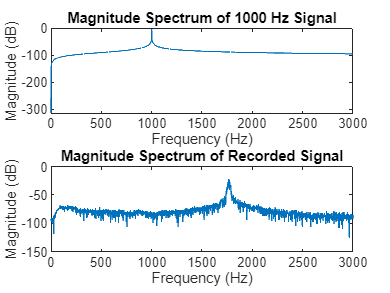

figure;
subplot(2,1,1);
plot(f_axis, 20*log10(f1_mag));
xlim([0 3000]);
title('Magnitude Spectrum of 1000 Hz Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(2,1,2);
plot(f_shifted, fftshift(20*log10(recorded_fft_magnitude)));
xlim([0 3000]);
title('Magnitude Spectrum of Recorded Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

## Reproducing the sound

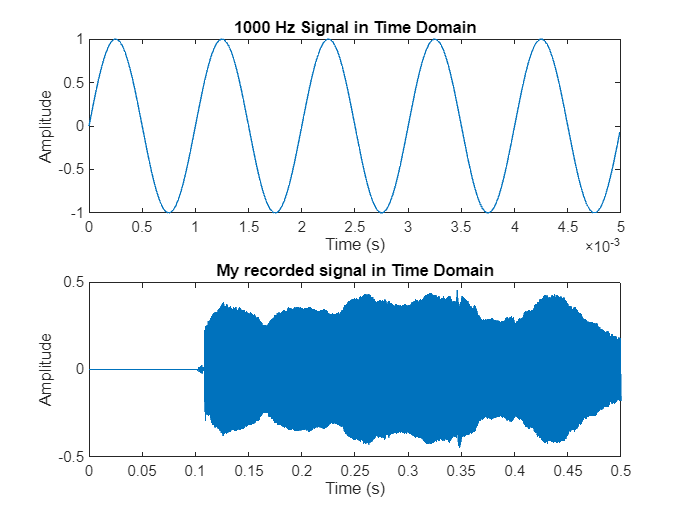

%converting the signals from discrete time domain to continous time domain
ctime_domain_sine = ifft(f1_fft);
ctime_domain_recorded = ifft(recorded_fft);

%reproducing the sound
sound(ctime_domain_sine, fs);
pause(T + 1);

sound(ctime_domain_recorded, fs);
pause(T + 1); 

%plotting
zoom = 0:1/fs:0.005; %I zoomed it to see clearly the signal
figure;
subplot(2,1,1);
plot(zoom, ctime_domain_sine(1:length(zoom)));
title('1000 Hz Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t_sin, ctime_domain_recorded(1:length(t_sin)));
title('My recorded signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');